미분방정식

(a) 3y(t)=x''(t)+4x'(t)+3x(t)

(b) y'(t)+2y(t)=x''(t)+4x'(t)+3x(t)

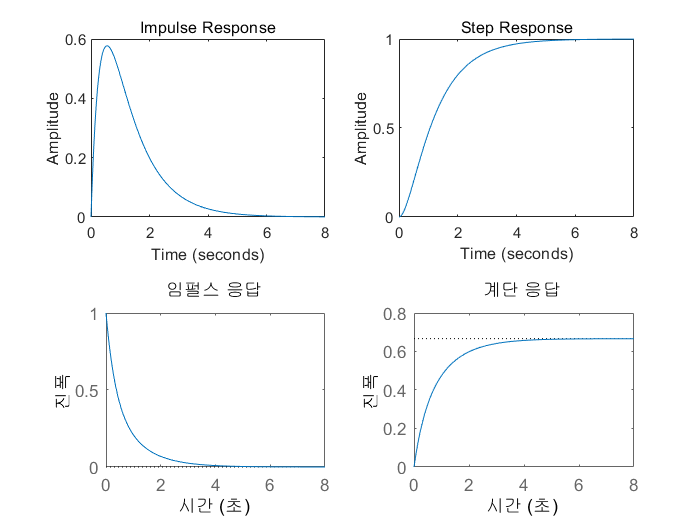

ti=0;tf=8;dt=0.02;t=ti:dt:tf;
dena=[1 4 3]; numa=[0 0 3]; % (a)의 출력항 및 입력항 계수
denb=dena; numb=[0 1 2]; % (b)의 출력항 및 입력항 계수
ha=impulse(numa,dena,t); % (a)의 임펄스 응답 h_a(t) 생성
sa=step(numa,dena,t); % (a)의 계단 응답 s_a(t) 생성
figure;
subplot(2,2,1); plot(t,ha); % (a)의 임펄스 응답
title('Impulse Response');
xlabel('Time (seconds)'); ylabel('Amplitude');
subplot(2,2,2); plot(t,sa); % (a)의 계단 응답
title('Step Response');
xlabel('Time (seconds)'); ylabel('Amplitude');
subplot(2,2,3); impulse(numb,denb,t); % (b)의 임펄스 응답
subplot(2,2,4); step(numb,denb,t); % (b)의 계단 응답